target = [42.2932850000000	-71.2643730000000];
current = [42.293252 -71.264429];
gridCoord = GPSToGrid(waypoints(i,:))
figure
hold on
plot(target(1),target(2),'kx','MarkerSize',60)
plot(current(1),current(2),'bx','MarkerSize',30)
leftcircle = [-78.3172   -0.1904];
r = 139.9943
viscircles(leftcircle(1,:),r)
New_Rover_Locations = [-218.3115   -0.1904]
plot(New_Rover_Locations(1),New_Rover_Locations(2),'x','MarkerSize',30)
hold off


**TEST FIND CIRCLE**

roverLocation = [4 7];
targetWaypoint = [2 3];
roverBearing = 300;
clf
[circle_center,radius] = findCircle(roverLocation, targetWaypoint, roverBearing)
hold on
plot(circle_center(1),circle_center(2),'gx',"MarkerSize",20)
hold off

**TEST ROVER GOING AT A CERTAIN SPEED ON TWO WAYPOINTS**

load final_waypoints.mat  %this will be loaded in as the variable "waypoints"
% start rover at first waypoint
roverPosition = waypoints(1,:);
roverPosition_grid = GPSToGrid(roverPosition);

% go to the second waypoint
targetWaypoint = waypoints(2,:);
targetWaypoint_grid = GPSToGrid(targetWaypoint);

roverBearing = 300;
clf
[circle_center,radius] = findCircle(roverPosition_grid, targetWaypoint_grid, roverBearing) % make sure to pass in the grid values

circle_center =    6.275760012343008  20.676881377241237


radius =    4.080843596894032


Find location of rover after travelling along the circle for a certain distance (determined by time)

time_elapsed = 3;

%NOTE: if we want to change the distance traveled, change the speed in
%function

% plot newRoverPosition, the rest of plotting done in findCircle and
% find_line functions
hold on
[newRoverPosition] = updateRoverPosition(roverPosition_grid, circle_center, radius, time_elapsed)

newRoverPosition =    5.429227248252008  16.684805884263749


scatter(newRoverPosition(1),newRoverPosition(2), "r",'DisplayName','newRoverPosition')
legend("Location", 'southoutside')
[m, b] = find_bearing_line(roverPosition_grid, roverBearing)

m =   -0.577350269189626


b =   19.588040811361903


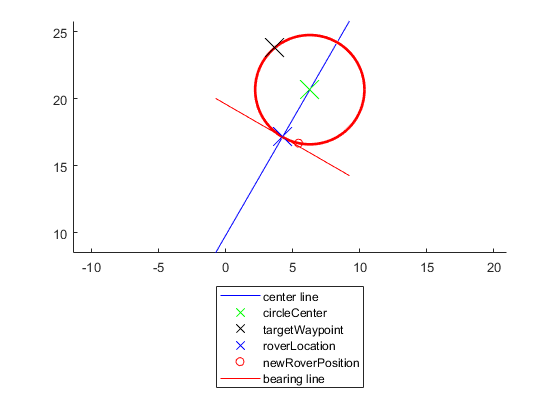

hold off

function [circle_center, radius] = findCircle(roverLocation, targetWaypoint, roverBearing)   
    %% find the equation of the circle given line and two points
    
    % find the equation of the line that i
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [m, c] = find_line(roverLocation, roverBearing);
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %y =  mx +  c
    %ax + by +  d = 0
    %mx - y +   c = 0
    a = m;
    b = -1;
    d = c;
    
    % equation of a circle
    % x2+y2+2gx+2fy+c=0 (-g,-f) is the center
    x1 = roverLocation(1); y1 = roverLocation(2);
    x2 = targetWaypoint(1); y2 = targetWaypoint(2);
    syms g f c
    eqn1 = x1^2 + y1^2 + 2*g*x1 + 2*f*y1 + c == 0;
    eqn2 = x2^2 + y2^2 + 2*g*x2 + 2*f*y2 + c == 0;
    
    % substitute g and f into the equation of the line
    eqn3 = a*-g + b*-f + d == 0;
    
    % solving the three equations
    sol = solve([eqn1, eqn2, eqn3], [g, f, c]);
    G = sol.g;
    F = sol.f;
    C = sol.c;
    
    % assigning the circle center
    circle_center = double([-G, -F]);
    
    % finding the radius
    radius = norm(circle_center - roverLocation);
    
    % sanity check to make sure its passing throught the points
    % this should be 0
    radius - norm(circle_center - targetWaypoint);
    
    %plotting
    hold on
        viscircles(circle_center,radius);
        plot(circle_center(1),circle_center(2),'gx',"MarkerSize",20, 'DisplayName','circleCenter')
        plot(targetWaypoint(1),targetWaypoint(2),'kx','MarkerSize',20, 'DisplayName','targetWaypoint')
        plot(roverLocation(1),roverLocation(2),'bx','MarkerSize',20, 'DisplayName', "roverLocation")
    hold off
    legend("Location", 'southoutside')
    axis equal
end

function [m, b] = find_line(roverPosition, roverBearing)
    % if robot bearing pointing in quad I and III
    x = roverPosition(1);
    y = roverPosition(2);
    omega = mod(roverBearing+90, 90);

    if ((roverBearing > 0 && roverBearing < 90) ||(roverBearing > 180 && roverBearing < 270))
%         disp("quad 1 3")
        omega = 90 - omega
        a = abs(y*tand(omega));
        x_int = a+x;
    elseif ((roverBearing > 90 && roverBearing < 180) ||(roverBearing > 270 && roverBearing < 360))
%         disp("quad 2 4")
        a = abs(y*tand(omega));
        x_int = x-a;
    end
    
    % plotting
    m = (y-0)/(x-x_int);
    b = y-m*x;
    
    hold on
    x= linspace(x-5,x+5, 10);
    y= m*x + b;
    
    plot(x, y, 'b', 'DisplayName','center line')
    axis equal
    hold off
end

function [direction] = CW_or_CCW(targetWaypoint, m, b)
    pt_on_line = (targetWaypoint(2) - b)/m % x coord of point of projected waypoint on rover bearing line
    if pt_on_line < targetWaypoint(1)
        direction =  "CW";
    else
        direction =  "CCW";
    end
end

function [m, b] = find_bearing_line(roverPosition, roverBearing)
    % if robot bearing pointing in quad I and III
    x = roverPosition(1);
    y = roverPosition(2);
    omega = mod(roverBearing, 90);

    if ((roverBearing > 0 && roverBearing < 90) ||(roverBearing > 180 && roverBearing < 270))
%         disp("quad 1 3")
        a = abs(y*tand(omega));
        x_int = x-a;
    elseif ((roverBearing > 90 && roverBearing < 180) ||(roverBearing > 270 && roverBearing < 360))
%         disp("quad 2 4")
        omega = 90-omega;
        a = abs(y*tand(omega));
        x_int = x+a;
    end
    m = (y-0)/(x-x_int);
    b = y-m*x;
    
    hold on
    x= linspace(x-5,x+5, 10);
    y= m*x + b;
    
    plot(x, y, 'r', 'DisplayName','bearing line')
    axis equal
    hold off

end


function [newRoverPosition] = updateRoverPosition(roverPosition_grid, circle_center, radius, time_elapsed)
    % find the location of the rover if we're rotating counterclockwise using this link:
        % https://math.stackexchange.com/questions/53875/calculating-point-around-circumference-of-circle-given-distance-travelled

    speed = 2.14/5; %m/s
    dist_traveled = speed*time_elapsed;
    
    % TODO: figure out whether we're traveling clockwise or counterclockwise
    
    
    %center
    a = circle_center(1);
    b = circle_center(2);
    
    %current location of of rover
    x = roverPosition_grid(1);
    y = roverPosition_grid(2);
    r = radius;
    
    phi = dist_traveled/r; % in radians
    
    newRoverPosition(1) = a+(x-a)*cos(phi) - (y-b)*sin(phi);   % circle math in radians
    newRoverPosition(2) = b+(x-a)*sin(phi) + (y-b)*cos(phi);
end


function [gridCoordinate] = GPSToGrid(GPSCoordinate)
    altitude = 10;
    % origin is at the bottom left corner
    origin = [42.29313067072105, -71.26442435650652, altitude];
    [gridCoordinate(1),gridCoordinate(2)] = latlon2local(GPSCoordinate(1), GPSCoordinate(2),altitude,origin);
end